Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# C-magnet, the upper half with shims (Section 4.3.2)

Volker Ziemann, 211109, CC-BY-SA-4.0

**Important:** this example requires the PDE toolbox!

Here we use the model of the upper half of the C-magnet and small pieces of iron to the ends of the pole gap, so-called *shims*,  in order to increase the extent of the region where the filed is constant. Therefore we just copy the description of the geometry from `CmagnetUpperHalf.mlx`

clear all; close all
Cmag=[2; 8; ...    %..Yoke
    0;0;0.3;0.3;1;1;-0.6;-0.6; ...
    0;0.3;0.3;0.05;0.05;0.8;0.8;0];
C1=[2;4;0;0;0.3;0.3;  0.1;0.3;0.3;0.1;zeros(8,1)];
C2=[2;4;1;1;1.3;1.3;  0.1;0.3;0.3;0.1;zeros(8,1)]; 
World=[2;4; -1;1.6;1.6;-1;0;0;1;1;zeros(8,1)]; 

and add the two small pieces of iron` S1` and `S2`  to the left and rright end of the pole gap. We parametrize its size by the width `dx` and height `dy` of the shims.

dx=0.050; dy=0.002; % shim width and height 50 mm x 2 mm
S1=[2;4;0.3;0.3+dx;0.3+dx;0.3;0.05-dy;0.05-dy;0.05;0.05;zeros(8,1)];     % left shim
S2=[2;4;0.95;0.95+dx;0.95+dx;0.95;0.05-dy;0.05-dy;0.05;0.05;zeros(8,1)]; % right shim

Now we are ready to define the geometry follwing the recipe used in the previous examples. Do not forget to add the shims!

gd=[World,Cmag,C1,C2,S1,S2];  % assemble geometry
ns=char('World','Cmag','C1','C2','S1','S2')';  % names of the regions                 
sf='World+Cmag+C1+C2+S1+S2'; 
g=decsg(gd,sf,ns);

After creating the model, we display the EdgeLabels, which allows us to specify the boundary conditions. This is equivalent to that section from `CmagnetUpperHalf.mlx.` Note that the there are many edges near the end of the pole gap. Those are the shims. Zoom in and inspect them.

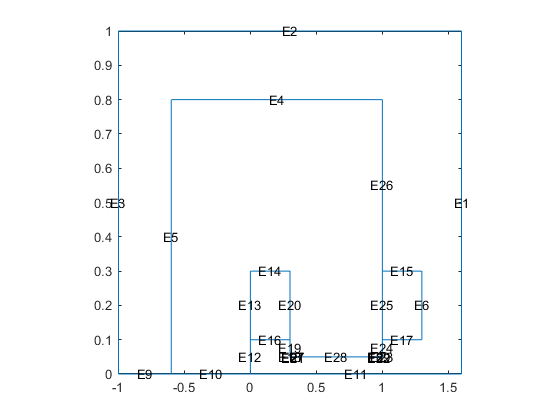

model=createpde(1);
geometryFromEdges(model,g);
pdegplot(model,'EdgeLabels','on');axis square 

applyBoundaryCondition(model,'Edge',[1:3],'u',0);
applyBoundaryCondition(model,'Edge',[9:11],'q',0,'g',0);

The next step is to inspect the SubDomainLabels and specify the material properties in the different regions. Again, note that the shims; they are named F4 and F6 now and we specify their coefficient `c = `$1/\mu_r$ to be that of iron.

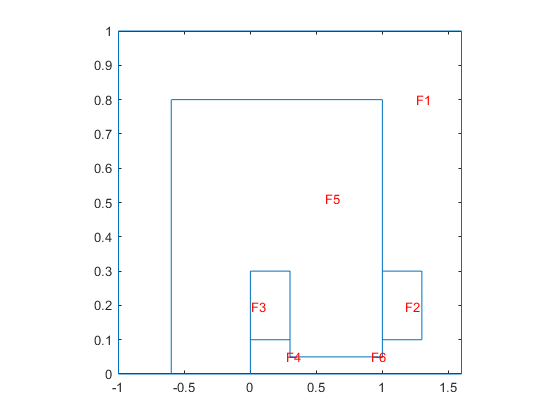

pdegplot(model,'SubDomainLabels','on'); 
axis square; 

specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0,'Face',1);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',-0.8378,'Face',2);
specifyCoefficients(model,'m',0,'d',0,'c',1,'a',0,'f',0.8378,'Face',3);
specifyCoefficients(model,'m',0,'d',0,'c',1/5000,'a',0,'f',0,'Face',4:6);

Now we generate the mesh with a smaller mesh size Hmax and furthermore note that the mesh becomes even smaller near the shims. Just zoom into the plot. Now we plot the potential, which is available as` result.NodalSolution` and superimpose the geometry.

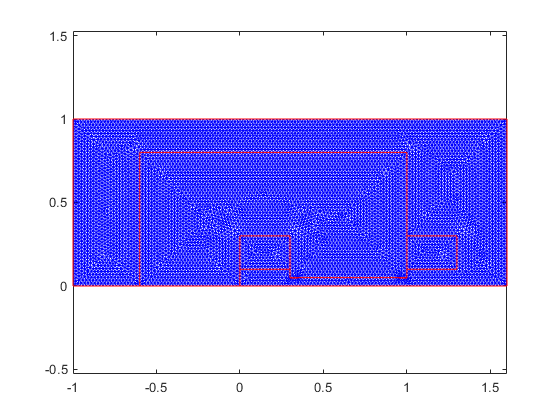

generateMesh(model,'Hmax',0.02); figure; pdemesh(model);

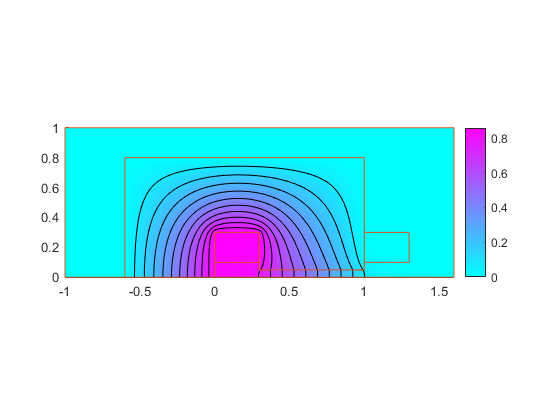

result=solvepde(model);
figure; 
pdeplot(model,'xydata',result.NodalSolution,'contour','on');
hold on; pdegplot(model)

The post-processing steps are the same as in `CmagnetUpperHalf.mlx.` We just calculate the magnitude of the magnetic field `Bn` and  plot it with contour lines and the geometry superimposed.

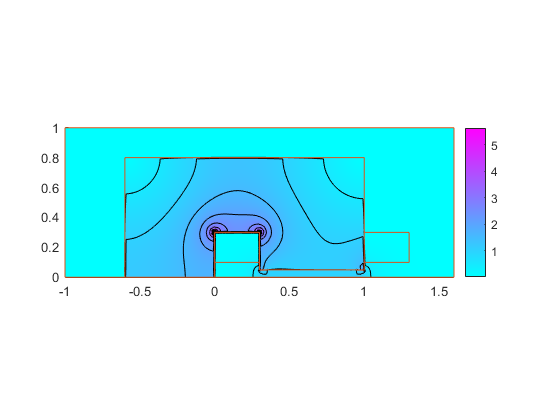

Bn=hypot(result.XGradients,result.YGradients);
figure; pdeplot(model,'xydata',Bn,'contour','on'); 
hold on; pdegplot(model);

Also the field in the gap is plotted. Here we observe that the 2mm shims actually bend the field at the edges a bit upwards. Thus, they are to high and we have to reduce the size to maybe 1mm, which is easily accomplished by  just changing `dy` where the  shims are defined. 

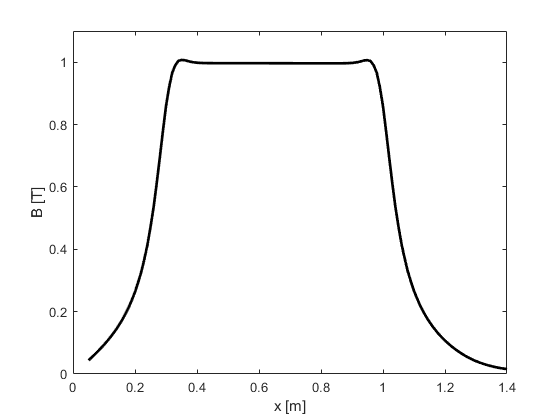

x=0.05:0.01:1.4; y=zeros(1,length(x));    % define line
[By,Bx]=evaluateGradient(result,x,y);  Bx=-Bx;
B=hypot(Bx,By);
figure; plot(x,B,'k','LineWidth',2)
xlabel('x [m]'); ylabel('B [T]'); ylim([0,1.1]); 

dlmwrite('Cmag_shim_2mm.dat',[x',B],'delimiter','\t');

Here we also write the magnetic field along the line into a file, such that we can later use it and compare configurations with shims of different sizes.